Definizione del **numeratore** e del **denominatore** della **FdT**.

num = [1 0];
den = [1 0 1];

sys = tf(num,den)


sys =
 
     s
  -------
  s^2 + 1
 
Continuous-time transfer function.
Model Properties


Tracciamento del **luogo delle radici positivo**.

- Per valori di K (con K > 0), i poli risiedono nel semipiano sinistro. Il sistema sarà asintoticamente stabile per ogni valore di K > 0.

- Affinchè i poli del sistema siano reali, K deve essere abbastanza elevato da spingere i poli sull'asse reale.

- Si calcola il valore di K' (slide p11, lez. 67) imponendo che poli e zeri della FdT ad anello chiuso valgano s = -1 (punto dove la curva blu e verde passano per l'asse reale negativo).

- Dall'equazione caratteristica D(s) + K'N(s) = 0, si pone "s = -1". Si ottiene quindi: 

- s^2 + 1 + K's = 0 |s = -1

- 1 + 1 - K' = 0 --> K' = 2

- Si ottiene quindi che per K' >= 2, tutti i poli del sistema avranno parte reale negativa.

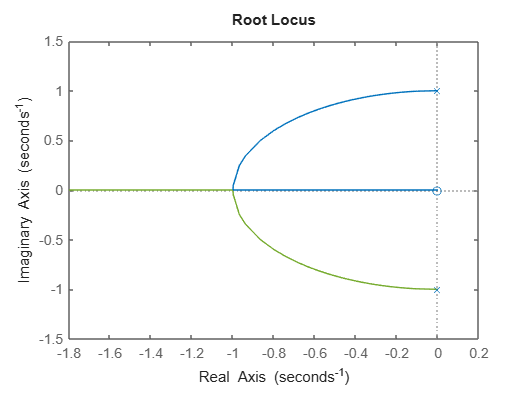

rlocus(num,den)

Tracciamento del **luogo delle radici negativo**.

- Per valori di K (con K < 0), tutti i poli sono nel semipiano destro.

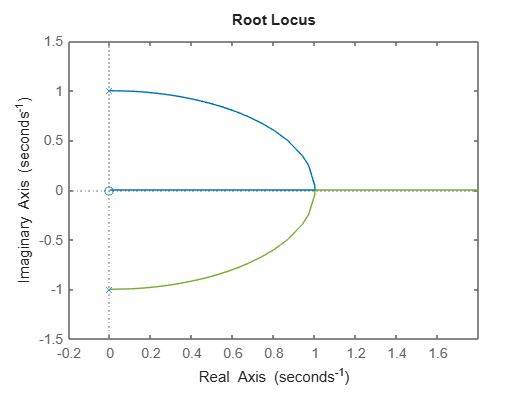

rlocus(-num,den)